# What Kind of Flower is That?

This example uses transfer learning to train a deep network that can classify images of flowers into one of 12 species.

## Get training images

flowerds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels));

## Create a network by modifying AlexNet

Get the layers from AlexNet

net = alexnet;
layers = net.Layers;

Modify the classification and output layers

layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;

## Set training algorithm options

Lower the learning rate for transfer learning

options = trainingOptions('sgdm','InitialLearnRate', 0.001);

## Perform training

[flowernet,info] = trainNetwork(trainImgs, layers, options);

Training on single GPU.
Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |        4.69% |       3.9194 |          0.0010 |
|      13 |          50 |       00:00:17 |      100.00% |       0.0080 |          0.0010 |
|      25 |         100 |       00:00:29 |      100.00% |       0.0025 |          0.0010 |
|      30 |         120 |       00:00:33 |      100.00% |       0.0048 |          0.0010 |
|========================================================================================|


## Use the trained network to classify test images

testpreds = classify(flowernet,testImgs);

## Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.8932

Visualize the confusion matrix

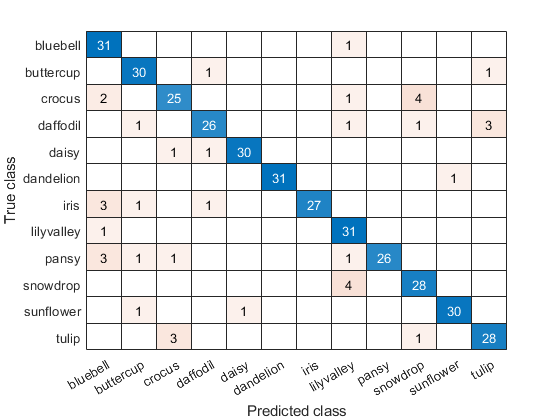

confusionchart(testImgs.Labels,testpreds);